# Working with Audio

## การอ่านไฟล์เสียง

audioFile1 = "Examples\Example1.wav";
audioFile2 = "Examples\Example2.wav";
audioFile3 = "Examples\Cycle1.wav";
audioFile4 = "Examples\Cycle2.wav";

[samples, Fs] = audioread(audioFile4);

- `x` คือ sample ของเสียงที่โหลดเข้ามา มีช่วงของค่าระหว่าง [-1.0, 1.0]

- `Fs` คือ sampling rate ในที่นี้คือ 48 kHz

fprintf("Sampling rate = %d Hz\n", Fs);

Sampling rate = 48000 Hz


fprintf("Audio length = %d samples (%.2f seconds)\n", length(samples), length(samples) / Fs);

Audio length = 242161 samples (5.05 seconds)



fprintf("The first few samples:\n");

The first few samples:


disp(x(1:100));

   -0.4960
   -0.4018
   -0.5143
   -0.5656
   -0.4480
   -0.3876
   -0.3818
   -0.4618
   -0.4690
   -0.5406
   -0.3426
   -0.1152
   -0.1348
   -0.1036
   -0.0798
   -0.0473
   -0.1573
   -0.3220
   -0.4609
   -0.4632
   -0.5538
   -0.6922
   -0.5643
   -0.4323
   -0.3047
   -0.3021
   -0.2241
   -0.3350
   -0.2548
   -0.0376
   -0.2135
   -0.3209
   -0.2478
   -0.3507
   -0.3882
   -0.3509
   -0.3188
   -0.4169
   -0.2151
    0.0566
    0.0677
    0.0467
    0.0230
    0.0092
    0.1762
    0.1859
    0.0613
    0.0795
    0.0192
    0.1643
    0.1296
    0.0903
    0.1750
    0.0395
    0.1205
    0.1366
    0.1302
    0.1278
    0.1303
    0.2208
    0.1915
    0.0831
    0.0762
    0.2121
    0.1134
    0.1365
   -0.0316
   -0.0552
    0.0668
   -0.1338
   -0.0661
   -0.0476
   -0.1161
   -0.0832
   -0.0747
    0.1246
    0.2315
    0.2217
    0.2191
   -0.0278
   -0.1943
   -0.1617
   -0.1194
   -0.1572
   -0.3336
   -0.6139
   -0.5272
   -0.5373
   -0.5025
   -0.3841
   -0.3123

## การแสดงและเล่นไฟล์เสียง

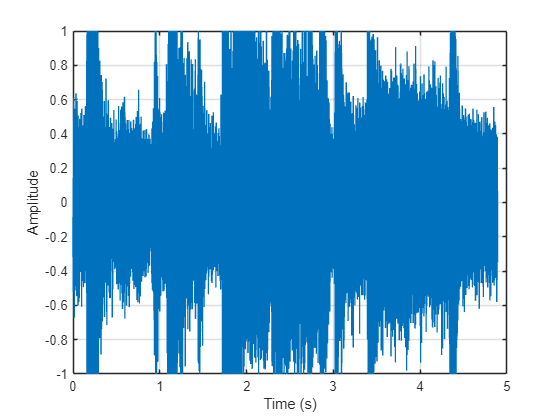

% chunk = samples(1:4800);
chunk = samples(1:end);

% Display the waveform
plot((1:length(chunk))/Fs, chunk);
xlabel("Time (s)");
ylabel("Amplitude");
grid("on");

% Playback the samples
player = audioplayer(samples, Fs); % must specify correct sampling rate
play(player);

stop(player); % use when wanting to stop long audio playback

ans = -3.3031e-04

## สัญญาณทดสอบ

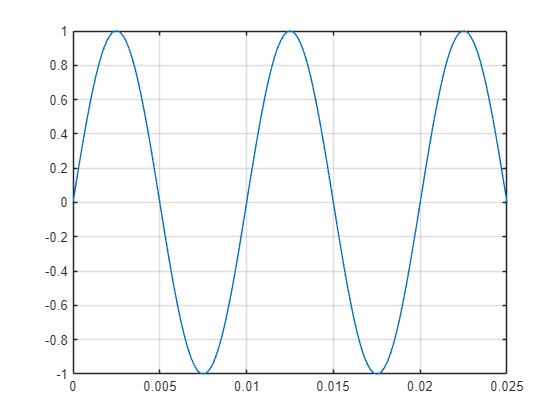

signalTime = 0.025; % total time in seconds
t = linspace(0, signalTime, round(signalTime * Fs));

testSignal1 = sin(2 * pi * 100 * t);
testSignal2 = cos(2 * pi * 1000 * t);
testSignal3 = testSignal1 .* testSignal2;

plot(t, testSignal1);
% hold on;
% plot(t, testSignal2);
% plot(t, testSignal3);
% hold off;
grid("on");

player = audioplayer(testSignal3, Fs); % must specify correct sampling rate
play(player);

## การบันทึกไฟล์เสียง

audiowrite("Examples/TestSignal.wav", testSignal3, Fs);